# Audio Processing in MATLAB - Complete Pipeline

clear; close all; clc;

## ========== 1. Load Audio File ==========

[signal, sr] = audioread('test.wav');
signal = mean(signal, 2);  % Convert to mono if stereo
signal = signal(1:min(length(signal), 10*sr));  % Use first 10 sec for demo

## ========== 2. Time Domain Visualization ==========

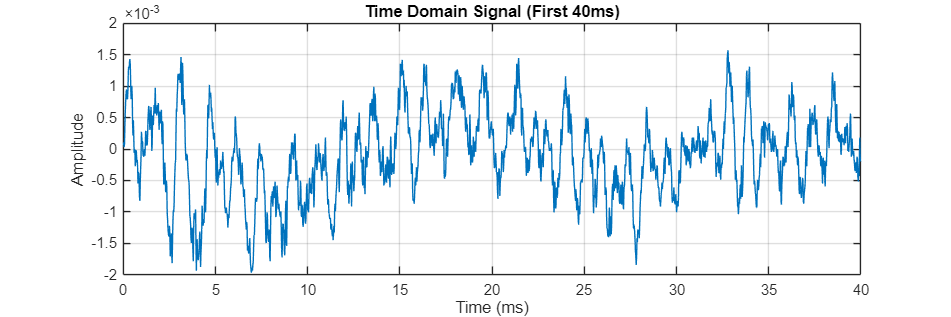

figure('Position', [100 100 1200 400]);
time_ms = (0:length(signal)-1)/sr*1000;  % Time axis in ms
zoom_samples = min(length(signal), round(0.040*sr));  % First 40ms

plot(time_ms(1:zoom_samples), signal(1:zoom_samples));
title('Time Domain Signal (First 40ms)');
xlabel('Time (ms)'); ylabel('Amplitude');
xlim([0 40]); grid on;

## ========== 3. Frequency Domain Analysis ==========

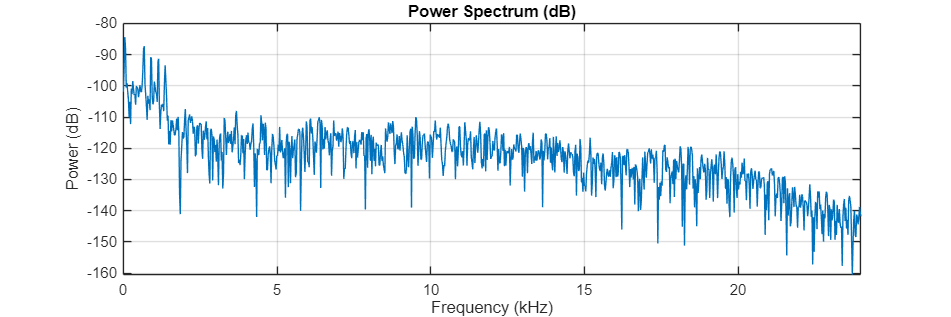

n_fft = 2048;
window = hamming(n_fft);

% Power Spectrum
[psd, freq] = periodogram(signal(1:n_fft), window, n_fft, sr);
figure('Position', [100 100 1200 400]);
plot(freq/1000, 10*log10(psd));
title('Power Spectrum (dB)');
xlabel('Frequency (kHz)'); ylabel('Power (dB)');
grid on; xlim([0 sr/2000]);

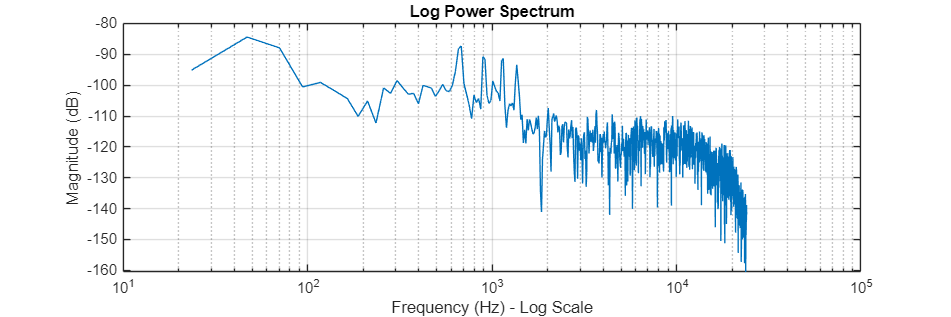


% Log Power Spectrum
figure('Position', [100 100 1200 400]);
semilogx(freq(2:end), 10*log10(psd(2:end)));  % Skip DC
title('Log Power Spectrum');
xlabel('Frequency (Hz) - Log Scale'); ylabel('Magnitude (dB)');
grid on;

## ========== 4. Cepstrum Analysis ==========

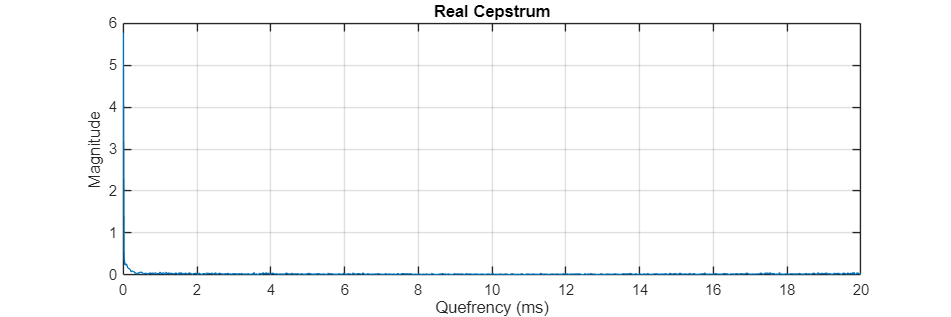

[cepstrum, quefrency] = cepstralAnalysis(signal(1:n_fft), sr);

figure('Position', [100 100 1200 400]);
plot(quefrency*1000, abs(cepstrum));
title('Real Cepstrum');
xlabel('Quefrency (ms)'); ylabel('Magnitude');
xlim([0 20]); grid on;

## ========== 5. Time-Frequency Analysis ==========

Spectrogram

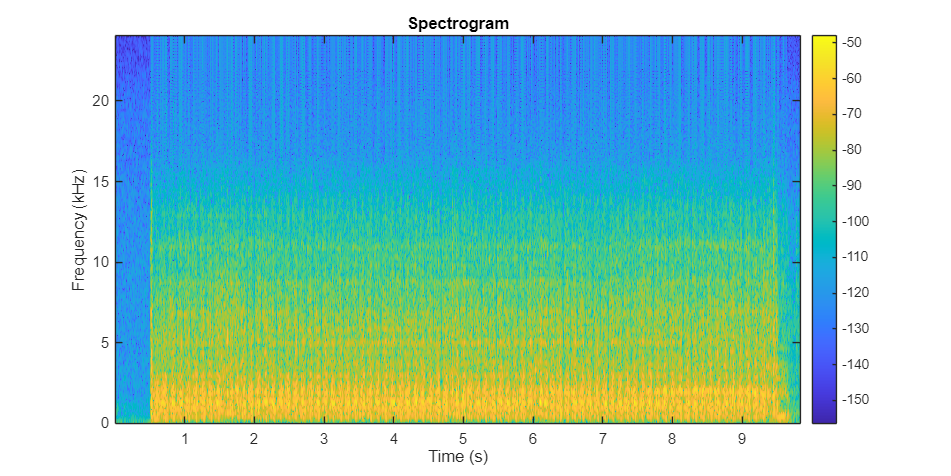

figure('Position', [100 100 1200 600]);
spectrogram(signal, 256, 128, 1024, sr, 'yaxis');
title('Spectrogram'); colorbar;


% Mel Spectrogram (requires Audio Toolbox)
if license('test', 'audio_toolbox')
    [melSpec, freqMel] = melSpectrogram(signal, sr, ...
        'Window', hamming(1024), ...
        'OverlapLength', 512, ...
        'FFTLength', 1024);

    figure('Position', [100 100 1200 400]);
    imagesc(10*log10(melSpec + eps));
    axis xy; colorbar;
    title('Mel Spectrogram (dB)');
    xlabel('Time (frames)'); ylabel('Mel Bands');
end

## ========== 6. Feature Extraction ==========

MFCCs (requires Audio Toolbox)

if license('test', 'audio_toolbox')
    mfccs = mfcc(signal, sr, 'LogEnergy', 'Ignore');
    mfcc_mean = mean(mfccs, 2)';
else
    mfcc_mean = [];
end

% Wavelet Features
[dwt_features, swt_features] = waveletFeatures(signal);

Error using swt (line 62)
Level of decomposition 3 and the length of the signal 472506 are not compatible. Suggested length: 472512. 2^Level must divide the length of the signal.

Error in untitled>waveletFeatures (line 95)
swc = swt(signal, 3, 'db4');


% Cepstral Features
cepstral_features = [mean(abs(cepstrum(1:100))), ...
    std(abs(cepstrum(1:100))), ...
    max(abs(cepstrum(1:100)))];

% Combine all features
features = [mfcc_mean, dwt_features, swt_features, cepstral_features];
disp(['Total features extracted: ' num2str(length(features))]);

## ========== Supporting Functions ==========

function [cepstrum, quefrency] = cepstralAnalysis(signal, sr)
n = length(signal);
spectrum = fft(signal.*hamming(n));
log_spectrum = log(abs(spectrum(1:n/2)) + eps);
cepstrum = ifft(log_spectrum);
quefrency = (0:length(cepstrum)-1)/sr;
end

function [dwt_features, swt_features] = waveletFeatures(signal)
% DWT Features
[coeffs, lengths] = wavedec(signal, 3, 'db4');
dwt_features = [];

for i = 1:3
    c = detcoef(coeffs, lengths, i);
    energy = sum(c.^2);
    std_dev = std(c);
    prob = abs(c)/sum(abs(c)) + eps;
    ent = -sum(prob.*log(prob));
    dwt_features = [dwt_features, energy, std_dev, ent];
end

% SWT Features
swc = swt(signal, 3, 'db4');
swt_features = [];

for i = 1:3
    detail = swc(i+3,:);
    swt_features = [swt_features, ...
        mean(detail), std(detail), sum(detail.^2)];
end
end